# Angle between the main-lobe of earth station antenna and terrestrial user

clc
clear all
sympref('FloatingPointOutput', true);

### Hourani

$\theta$: orientation of the main-lobe of earth station antenna

syms theta phi1 pi2 
r_e= 6371e3

r_e = 6371000

h= 800e3

h = 800000

N= 100

N = 100

gamma = 1 + h/r_e

gamma = 1.1256

phi1 = acot( (gamma^2*tan(theta) + sqrt(gamma^2*(sec(theta))^2 -1) )/(gamma^2-1)  )

$$phi1 = \mathrm{acot}\left(4.7466\,\tan\left(\theta \right)+3.7466\,\sqrt{\frac{1.2669}{{\cos\left(\theta \right)}^{2}}-1}\right)$$

phi2 = acot( (gamma^2*tan(theta) - sqrt(gamma^2*(sec(theta))^2 -1) )/(gamma^2-1)  )

$$phi2 = \mathrm{acot}\left(4.7466\,\tan\left(\theta \right)-3.7466\,\sqrt{\frac{1.2669}{{\cos\left(\theta \right)}^{2}}-1}\right)$$

pdf of $\theta$

d1 = abs(diff(phi1, theta))

$$d1 = \frac{\left|4.7466\,{\tan\left(\theta \right)}^{2}+\frac{4.7466\,\sin\left(\theta \right)}{{\cos\left(\theta \right)}^{3}\,{\left(\frac{1.2669}{{\cos\left(\theta \right)}^{2}}-1\right)}^{0.5000}}+4.7466\right|}{\left|{\left(4.7466\,\tan\left(\theta \right)+3.7466\,\sqrt{\frac{1.2669}{{\cos\left(\theta \right)}^{2}}-1}\right)}^{2}+1\right|}$$

d2 = abs(diff(phi2, theta))

$$d2 = \frac{\left|4.7466\,{\tan\left(\theta \right)}^{2}-\frac{4.7466\,\sin\left(\theta \right)}{{\cos\left(\theta \right)}^{3}\,{\left(\frac{1.2669}{{\cos\left(\theta \right)}^{2}}-1\right)}^{0.5000}}+4.7466\right|}{\left|{\left(4.7466\,\tan\left(\theta \right)-3.7466\,\sqrt{\frac{1.2669}{{\cos\left(\theta \right)}^{2}}-1}\right)}^{2}+1\right|}$$

f_theta(theta) =  (N/2)*sin(phi1)*exp(-(N/2)*(1- cos(phi1)))*d1 

$$f\_theta(theta) = \begin{array}{l} \frac{50\,{\mathrm{e}}^{\frac{50}{\sigma_{1}}-50}\,\left|4.7466\,{\tan\left(\theta \right)}^{2}+\frac{4.7466\,\sin\left(\theta \right)}{{\cos\left(\theta \right)}^{3}\,{\left(\frac{1.2669}{{\cos\left(\theta \right)}^{2}}-1\right)}^{0.5000}}+4.7466\right|}{\left|{\sigma_{2}}^{2}+1\right|\,\sigma_{1}\,\sigma_{2}}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{1}{{\sigma_{2}}^{2}}+1\right)}^{0.5000}\\ \sigma_{2}=4.7466\,\tan\left(\theta \right)+3.7466\,\sqrt{\frac{1.2669}{{\cos\left(\theta \right)}^{2}}-1} \end{array}$$

f_1_theta = matlabFunction(f_theta)

f_1_theta = function_handle with value:
    @(theta)(exp(1.0./sqrt(1.0./(tan(theta).*4.746643867227886+sqrt(1.0./cos(theta).^2.*1.266905538780202-1.0).*3.746643867227886).^2+1.0).*5.0e+1-5.0e+1).*abs(tan(theta).^2.*4.746643867227886+1.0./cos(theta).^3.*sin(theta).*1.0./sqrt(1.0./cos(theta).^2.*1.266905538780202-1.0).*4.746643867227886+4.746643867227886).*1.0./sqrt(1.0./(tan(theta).*4.746643867227886+sqrt(1.0./cos(theta).^2.*1.266905538780202-1.0).*3.746643867227886).^2+1.0).*5.0e+1)./(abs((tan(theta).*4.746643867227886+sqrt(1.0./cos(theta).^2.*1.266905538780202-1.0).*3.746643867227886).^2+1.0).*(tan(theta).*4.746643867227886+sqrt(1.0./cos(theta).^2.*1.266905538780202-1.0).*3.746643867227886))


x_theta = linspace(0, pi/2);
m = length(x_theta)

m = 100


f_theta_val = zeros(1,m);
for j = [1:m]
    f_theta_val(j) = f_1_theta(x_theta(j));
end

G_hourani = zeros(1, length(x_theta));

for j=[1:m]
    G_hourani(j) = integral(f_1_theta, 0, x_theta(j));
end


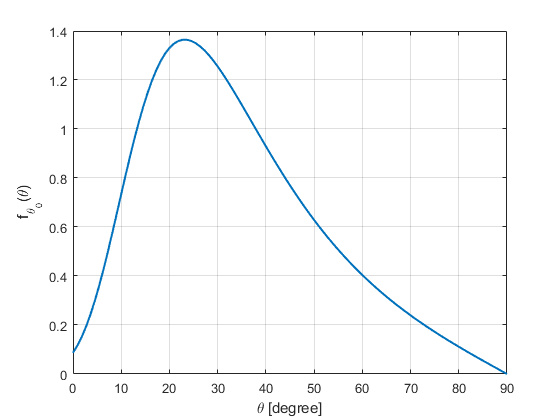

figure
plot(rad2deg(x_theta), f_theta_val, 'LineWidth', 1.5)
xlabel('\theta [degree]')
ylabel('f_{\theta_0}(\theta)')
grid on;

epsilon = 1e-3;
f_int_theta_full = integral(@(theta)f_1_theta(theta), 0,  pi/2, 'ArrayValued',true)

f_int_theta_full = 0.9962

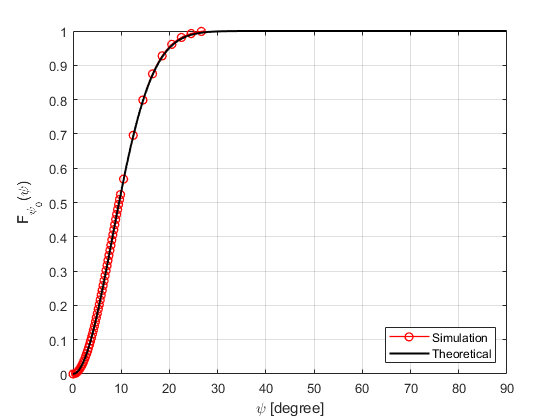

a = csvread('D:\Satellites\28GHz\data\psi0.csv');

psi_vec = [0:0.01:pi/2];
F_psi = 1 - exp(-(N/2.0)*(1.0-cos(psi_vec)));

[y,x] = hist(a, 30);
[y1, x1] = ecdf(a);
y = y/sum(y);

figure;
plot(x1, y1, 'ro-', 'LineWidth', 1, 'MarkerIndices', 1:2000:length(x1))
hold on
plot(rad2deg(psi_vec), F_psi, 'k-', 'LineWidth', 1.5)

legend('Simulation', 'Theoretical', 'Location',"southeast")
xlabel('\psi [degree]')
ylabel('F_{\psi_0}(\psi)')

xlim([0 90])
ylim([0 1])
grid on;
box on;

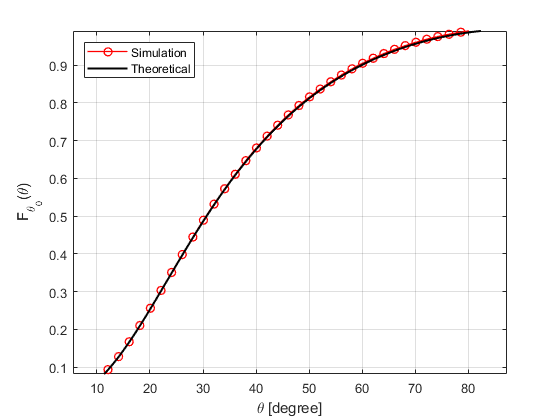

a = csvread('D:\Satellites\28GHz\data\theta0.csv');

[y1, x1] = ecdf(a);
figure;
plot(x1, y1, 'ro-', 'LineWidth', 1, 'MarkerIndices', 1:2000:length(x1))
hold on
plot(rad2deg(x_theta), G_hourani, 'k-', 'LineWidth', 1.5)

legend('Simulation', 'Theoretical', 'Location',"northwest")
xlabel('\theta [degree]')
ylabel('F_{\theta_0}(\theta)')

xlim([0 90])
ylim([0 1])
grid on;
box on;

syms v alpha

f_alpha_pre_int(v, alpha) = sin(alpha)*f_theta(acos(v))/(pi*sqrt( (1-v^2)*(v^2 - (cos(alpha))^2 ) ))

$$f\_alpha\_pre\_int(v, alpha) = \begin{array}{l} \frac{15.9155\,{\mathrm{e}}^{\frac{50}{\sigma_{1}}-50}\,\left|\frac{4.7466\,\sqrt{1-v^{2}}}{v^{3}\,{\left(\frac{1.2669}{v^{2}}-1\right)}^{0.5000}}-\frac{4.7466\,\left(v^{2}-1\right)}{v^{2}}+4.7466\right|\,\sin\left(\alpha \right)}{\left|{\sigma_{2}}^{2}+1\right|\,{\left(\left(v^{2}-1\right)\,\left({\cos\left(\alpha \right)}^{2}-v^{2}\right)\right)}^{0.5000}\,\sigma_{1}\,\sigma_{2}}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{1}{{\sigma_{2}}^{2}}+1\right)}^{0.5000}\\ \sigma_{2}=\frac{4.7466\,\sqrt{1-v^{2}}}{v}+3.7466\,\sqrt{\frac{1.2669}{v^{2}}-1} \end{array}$$

f_alpha_pre_int(cos(0.1), 0.1)

$$ans = -1.1473e+07\,\mathrm{i}$$

f_alpha_pre_int_mat = @(v1, a1) matlabFunction(f_alpha_pre_int(v1, a1))

f_alpha_pre_int_mat = function_handle with value:
    @(v1,a1)matlabFunction(f_alpha_pre_int(v1,a1))


x_alpha = linspace(0, pi);
m = length(x_alpha)

m = 100

f_alpha_val = zeros(1,m);
for j = [1:m]
    f_alpha_val(j) = double(vpaintegral(f_alpha_pre_int(v, x_alpha(j)),...
        v, abs(cos(x_alpha(j))), 1));
end

$\alpha$: angle between the main-lobe of earth station antenna and terrestrial user

figure
plot(rad2deg(x_alpha), f_alpha_val, 'LineWidth', 1.5)

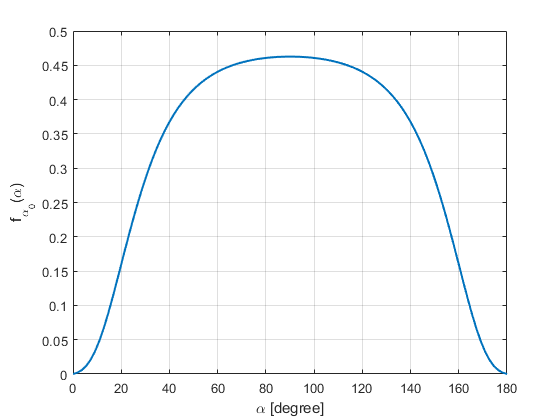

xlabel('\alpha [degree]')
ylabel('f_{\alpha_0}(\alpha)')
grid on;